# Does CICE behave the same when wave forcing is turned off and when waves are set to 0?

The goal of this document is to determine whether CICE will produce the same results with wave forcing turned off (wave_spec_type = none), with significant wave height being set to 0, and with signficant wave height determined by the WIM. To do this, first we look at the intergrated quantities (ice concentration) and compare these results, we expect these to be indistringuishable. There are two outcomes:

- If they are the same, great! The amount of new ice is the same, but is it being allocated to the FSD appropriately?

- If there is a difference, then where is this coming from?

After understanding the difference between no wave forcing and a SWH of 0 m, we will look at the impact non-zero SWHs.

% Set the parameters
close all; clear all; addpath functions; addpath packages/bedmap2_toolbox_v4
grid = 'gx1'; sector = "SH";
case_noforcing = 'forcingoff'; case_nowaves = 'wimoff';
grid = 'gx1'; 
day = 1; month_init = 9; year = 2005;
date = sprintf('%d-0%d-0%d', year, month_init, day);
figcount = 0;

filename1 = strcat('cases/',case_noforcing,"/history/iceh.",date,".nc");filename2 = strcat('cases/',case_nowaves,"/history/iceh.",date,".nc");
[lat, lon, row] = grid_read(grid);
NFSD = ncread(filename1,"NFSD"); NCAT = ncread(filename1,"NCAT");
Nf = 16; Nc = 5;
lims = [6.65000000e-02,   5.31030847e+00,   1.42865861e+01,   2.90576686e+01, 5.24122136e+01,   8.78691405e+01,   1.39518470e+02,   2.11635752e+02, 3.08037274e+02,   4.31203059e+02,   5.81277225e+02,   7.55141047e+02, 9.45812834e+02,   1.34354446e+03,   1.82265364e+03,   2.47261361e+03,  3.35434988e+03];
floe_rad_l = [lims(1:Nf)]; % Floe radius lower bound
floe_rad_h = lims(2:Nf+1); % Floe radius higher bound
floe_binwidth = floe_rad_h - floe_rad_l;
floe_rad_c = (floe_rad_l+floe_rad_h)/2;

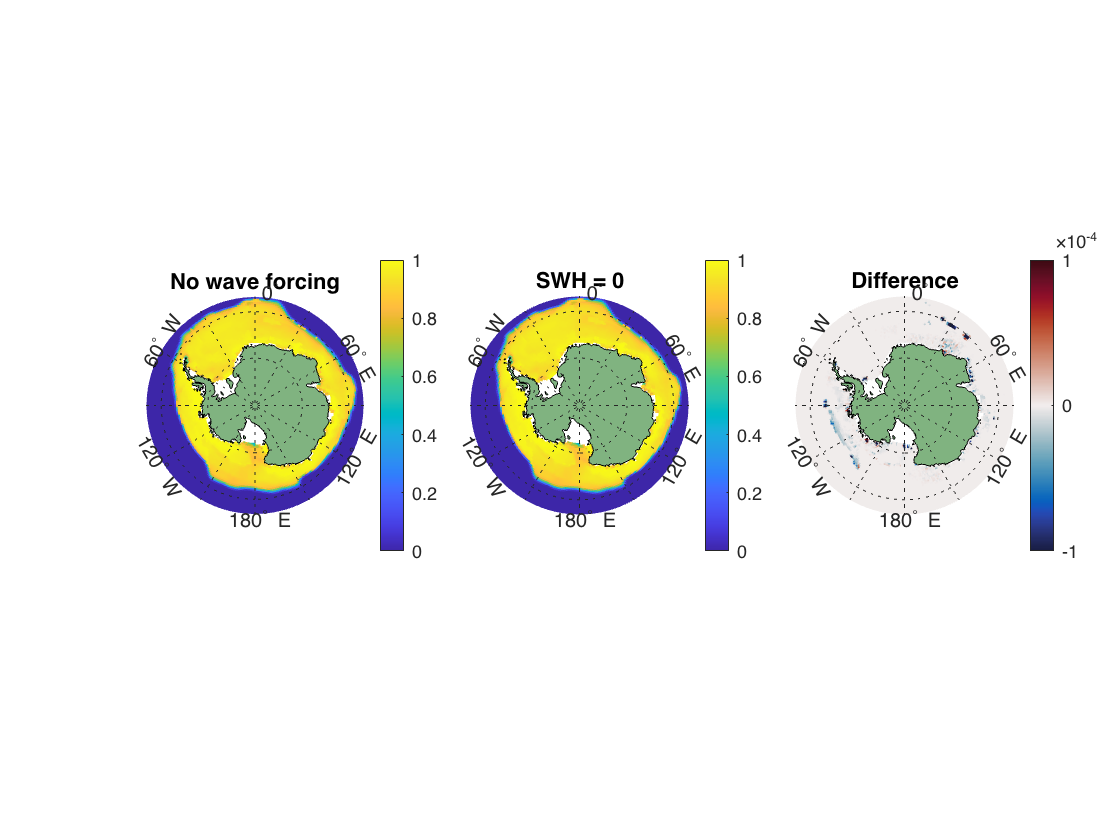

%% Now read in the data

% First we look at aice after 1 day
aice1 = data_format_sector(filename1,"aice",sector);
aice2 = data_format_sector(filename2,"aice",sector);


tp = tiledlayout(1,3);
nexttile
map_plot(aice1,"aice",sector);  
title("No wave forcing")
nexttile
map_plot(aice2,"aice",sector); 
title("SWH = 0")
nexttile
map_plot(aice1-aice2,"aice",sector,grid,[-0.0001,0.0001]); 
title('Difference')
cmocean('balance')

Figure 1a. Ice concentration with no wave forcing.

Figure 1b. Ice concentration with waves of 0 height.

Figure 1c. There is a small (but signficant!) difference in aice (no wave forcing - 0 wave height) after 1 day. This occurs primarily around the ice edge but also noticeabley at the coast around 40 E.

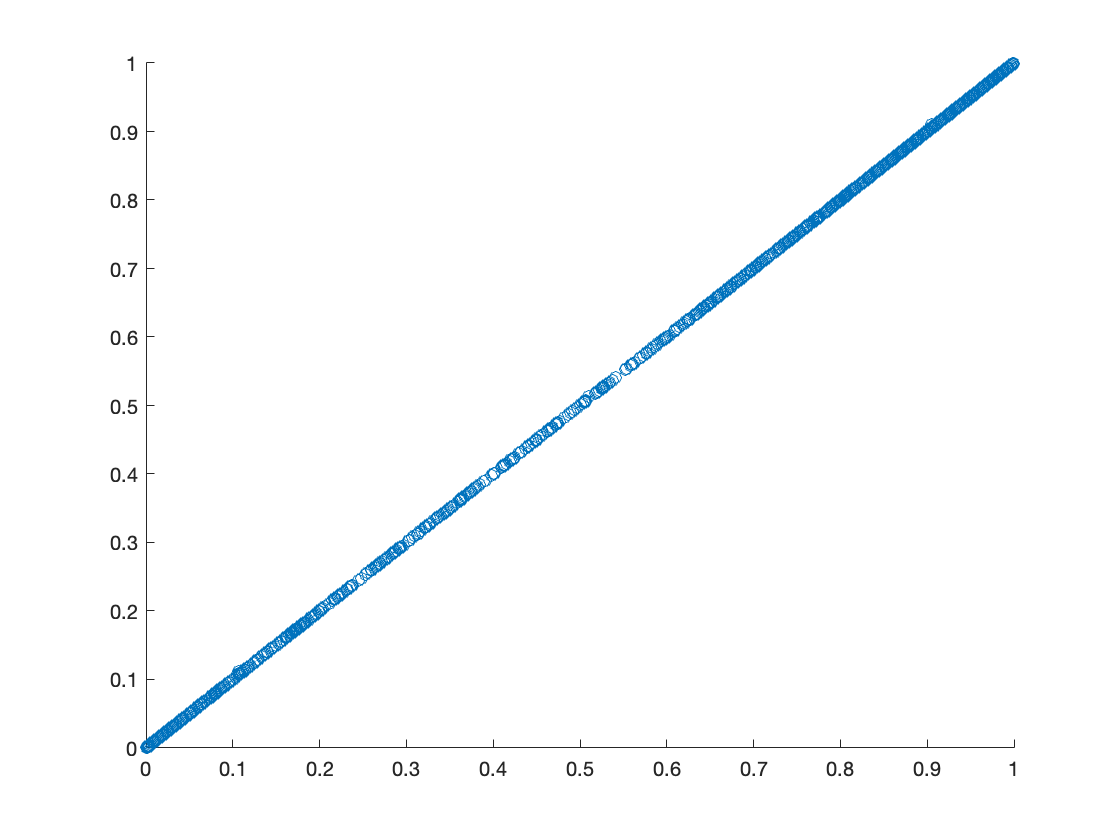

figure(2)
scatter(aice1(1:numel(aice1)),aice2(1:numel(aice1)))

Figure 2. aice from case 1 vs aice from case 2 across the Southern Hemisphere. As we expect the change isn't major, but how big is it?

corr(aice1(~isnan(aice1)),aice2(~isnan(aice1)))

ans = 1.0000

maxerror = max(max(abs(aice1(~isnan(aice1))-aice2(~isnan(aice1)))))

maxerror = 0.0058

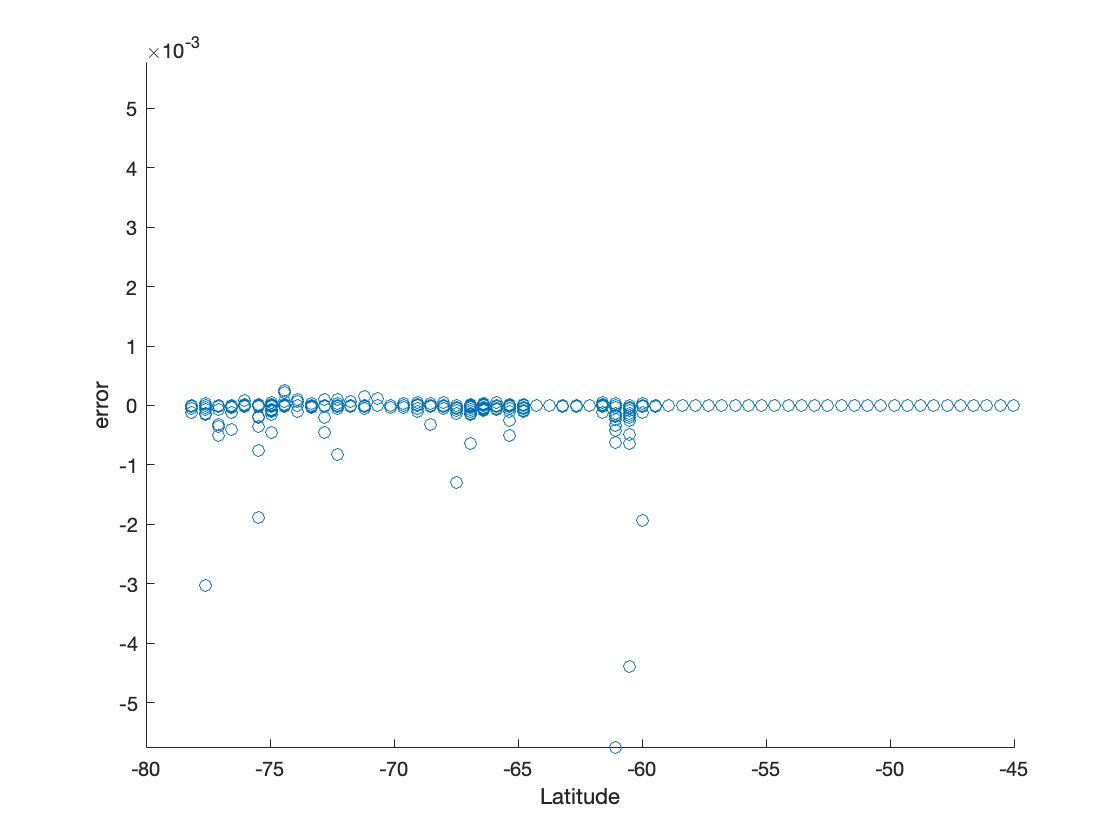

figure(3)
scatter(lat(1:numel(lat)),aice1(1:numel(lat))-aice2(1:numel(lat)))
xlabel('Latitude')
ylabel('error')
ylim([-maxerror,maxerror])

From Figure 3. we see that most of the error occurs near the Antarctic coast or by the ice edge. The maximum error is 0.0058 which is a 0.05% change in ice concentration for a single cell.

#### Plot results from the cell in which the maximum change has occurred

%% Find the cell that has the most error
diffaice = aice1-aice2;
cell_matrix = diffaice == -maxerror;
[nx,ny] = size(cell_matrix);
xcell = find(sum(cell_matrix'))

xcell = 38

ycell = find(sum(cell_matrix));
diffaice(xcell,ycell);

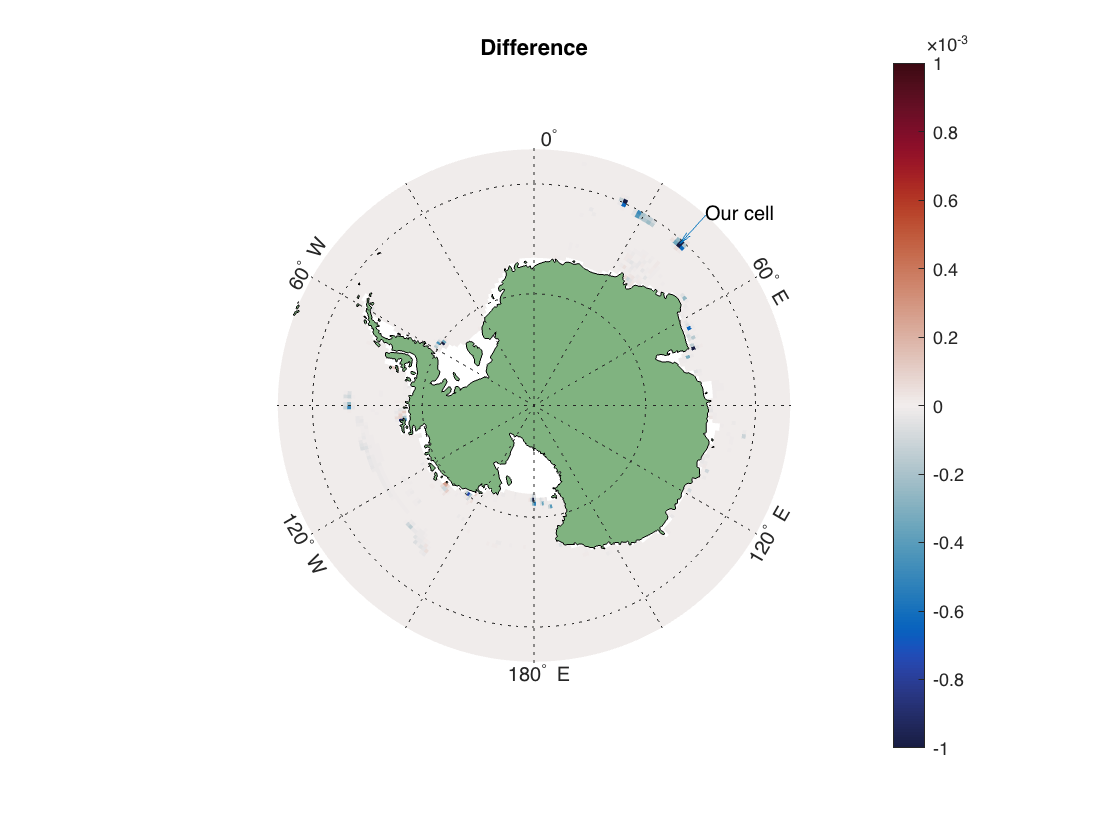


% Now we have the cell, what is going on in here?

figure(4)
map_plot(aice1-aice2,"aice",sector,grid,[-0.001,0.001]); 
title('Difference')
cmocean('balance')
quiverm(lat(xcell,ycell)+6,lon(xcell,ycell)+0.5,-5.5,0)
textm(lat(xcell,ycell)+6,lon(xcell,ycell), 1, 'Our cell')


% Changes in FSD
dafsd_latm1 = data_format_sector(filename1,"dafsd_latm",sector);
dafsd_latg1 = data_format_sector(filename1,"dafsd_latg",sector);
dafsd_newi1 = data_format_sector(filename1,"dafsd_newi",sector);
dafsd_weld1 = data_format_sector(filename1,"dafsd_weld",sector);
dafsd_wave1 = data_format_sector(filename1,"dafsd_wave",sector);

dafsd_latm2 = data_format_sector(filename2,"dafsd_latm",sector);
dafsd_latg2 = data_format_sector(filename2,"dafsd_latg",sector);
dafsd_newi2 = data_format_sector(filename2,"dafsd_newi",sector);
dafsd_weld2 = data_format_sector(filename2,"dafsd_weld",sector);
dafsd_wave2 = data_format_sector(filename2,"dafsd_wave",sector);

clear data1 data2
data1(:,:) = [dafsd_latm1(xcell,ycell,:), dafsd_latg1(xcell,ycell,:), dafsd_newi1(xcell,ycell,:), dafsd_weld1(xcell,ycell,:), dafsd_wave1(xcell,ycell,:)];
data2(:,:) = [dafsd_latm2(xcell,ycell,:), dafsd_latg2(xcell,ycell,:), dafsd_newi2(xcell,ycell,:), dafsd_weld2(xcell,ycell,:), dafsd_wave2(xcell,ycell,:)];

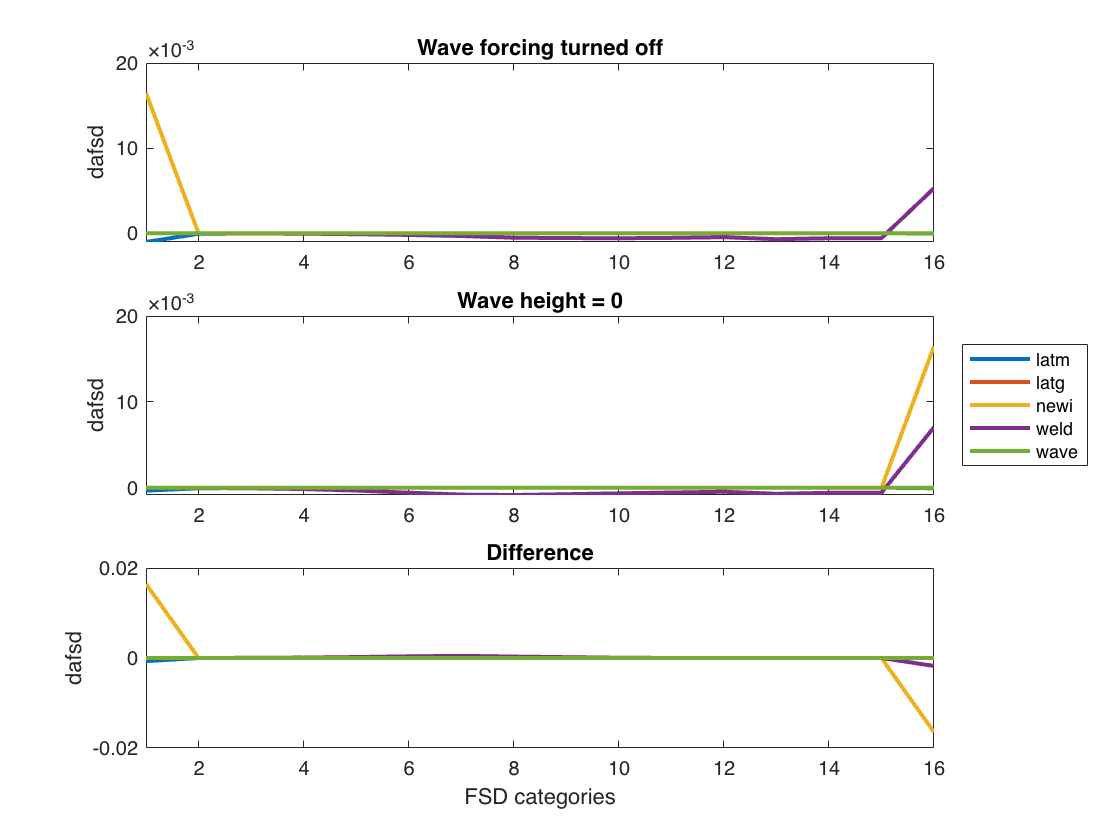

% Plotting
clear t1 t2
figure(5);
t1 = tiledlayout(3,1,'TileSpacing','compact');
%title(sprintf("Cell at (%g S, %g E)",lat(xcell,ycell),lon(xcell,ycell)))
nexttile
f1 = plot(data1','LineWidth',2);
ylabel('dafsd')
xlim([1,16])
title(sprintf('Wave forcing turned off',lat(xcell,ycell),lon(xcell,ycell)))
nexttile
plot(data2','LineWidth',2)
legend({'latm','latg','newi','weld','wave'},'Location','eastoutside')
xlim([1,16])
ylabel('dafsd')
title(sprintf('Wave height = 0',lat(xcell,ycell),lon(xcell,ycell)))
nexttile
plot(data1'- data2','LineWidth',2)
xlabel('FSD categories')
xlim([1,16])
ylabel('dafsd')
title('Difference')

New ice is being assigned to the largest FSD when waves are of height 0, which makes sense from the Shen model. With no wave forcing, new ice floes are assigned to the smallest FSD category.

ND: Is this assumption a good one however?

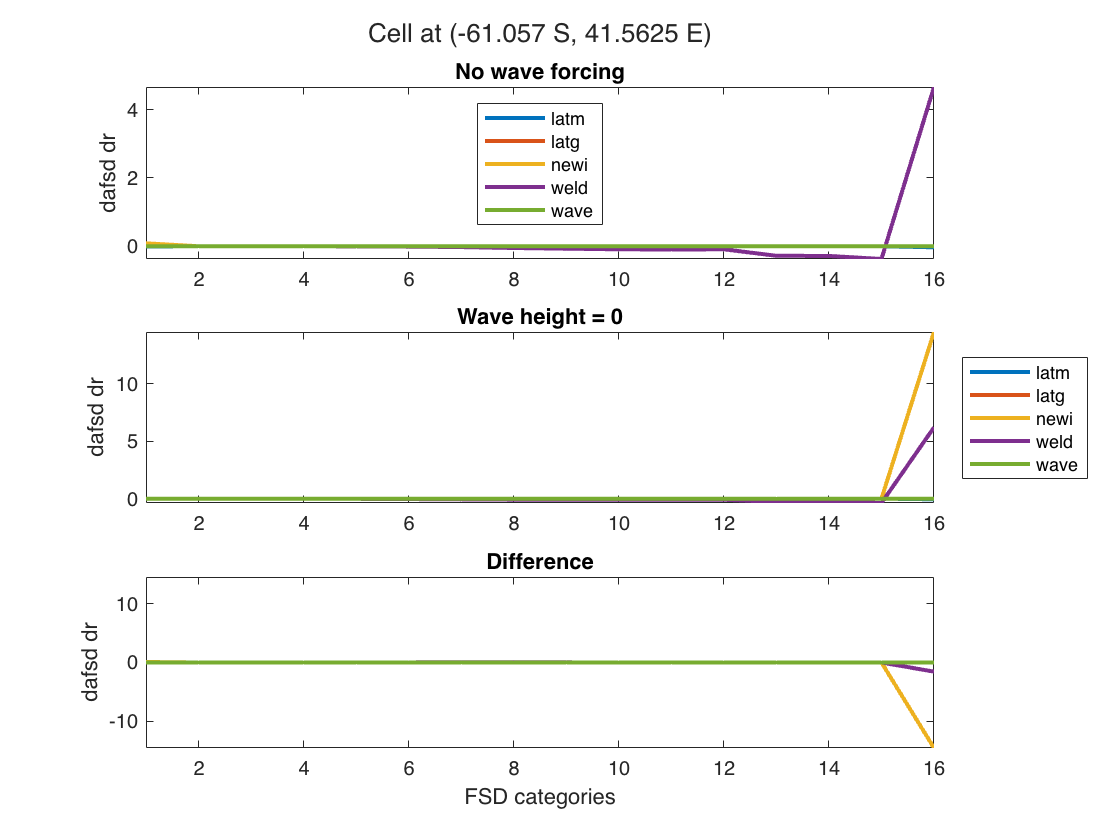

figure(6) 
t2 = tiledlayout(3,1,'TileSpacing','compact');
title(t2,sprintf('Cell at (%g S, %g E)',lat(xcell,ycell),lon(xcell,ycell)))
nexttile
floe_width_mat = [floe_binwidth;floe_binwidth;floe_binwidth;floe_binwidth;floe_binwidth];
plot(data1'.*floe_width_mat','LineWidth',2)
xlim([1,16])
legend({'latm','latg','newi','weld','wave'},'Location','north')
ylabel('dafsd dr')
title(sprintf('No wave forcing',lat(xcell,ycell),lon(xcell,ycell)))
nexttile
floe_width_mat = [floe_binwidth;floe_binwidth;floe_binwidth;floe_binwidth;floe_binwidth];
plot(data2'.*floe_width_mat','LineWidth',2)
legend({'latm','latg','newi','weld','wave'},'Location','eastoutside')
xlim([1,16])
ylabel('dafsd dr')
title('Wave height = 0')
nexttile
plot((data1'- data2').*floe_width_mat','LineWidth',2)
xlabel('FSD categories')
xlim([1,16])
ylabel('dafsd dr')
ylim([-max(max(abs((data1'- data2').*floe_width_mat'))),max(max(abs((data1'- data2').*floe_width_mat')))])
title('Difference')

So what we see is that the change in afsd is assigned to either category 1 or 16, BUT when we look at the change in areal concentration (by multiplying by floe bin width) then it "appears" as if minimal new floes are being formed, whereas IN FACT the same number of floes are being produced, but they are so small that the cumulative new ice area is still hardly noticeable.

ND: Does it make sense for so much more freezing to occur when the wave height is 0? Is the model without wave forcing assuming that waves will have the effect of breaking them up?

## WIM on vs WIM off

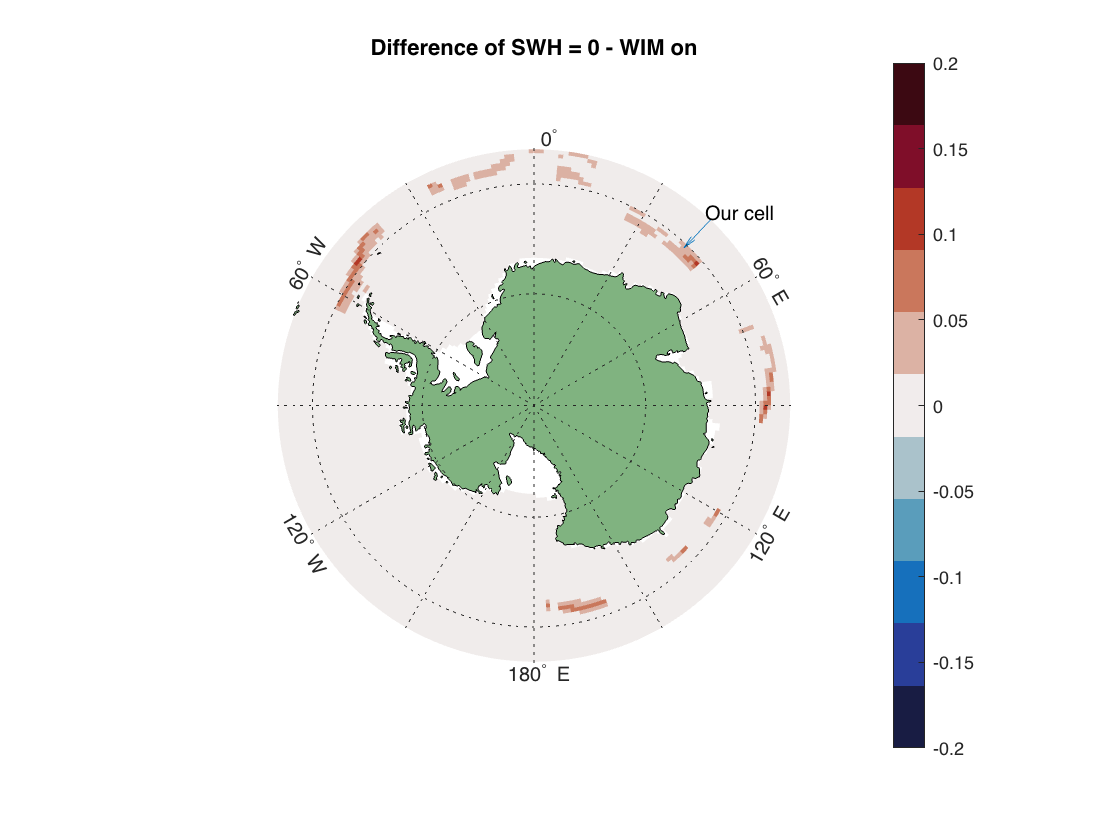

% Read in data
filename3 = strcat('cases/','wimon',"/history/iceh.",date,".nc");
aice3 = data_format_sector(filename3,"aice",sector);

% Plot the difference of aice for cases when SWH = 0 and SWH from WIM 
figure(7)
map_plot(aice2-aice3,"aice",sector,grid,[-0.2,0.2]); 
quiverm(lat(xcell,ycell)+6,lon(xcell,ycell)+2,-5.5,0)
textm(lat(xcell,ycell)+6,lon(xcell,ycell), 1, 'Our cell')
title('Difference of SWH = 0 - WIM on')
cmocean('balance',11)

There is a much more considerable change in the ice concentration when we compare SWH = 0 and SWH calculated by WIM.

% Read in the change in FSD data
dafsd_latm3 = data_format_sector(filename3,"dafsd_latm",sector);
dafsd_latg3 = data_format_sector(filename3,"dafsd_latg",sector);
dafsd_newi3 = data_format_sector(filename3,"dafsd_newi",sector);
dafsd_weld3 = data_format_sector(filename3,"dafsd_weld",sector);
dafsd_wave3 = data_format_sector(filename3,"dafsd_wave",sector);
data3(:,:) = [dafsd_latm3(xcell,ycell,:), dafsd_latg3(xcell,ycell,:), dafsd_newi3(xcell,ycell,:), dafsd_weld3(xcell,ycell,:), dafsd_wave3(xcell,ycell,:)];

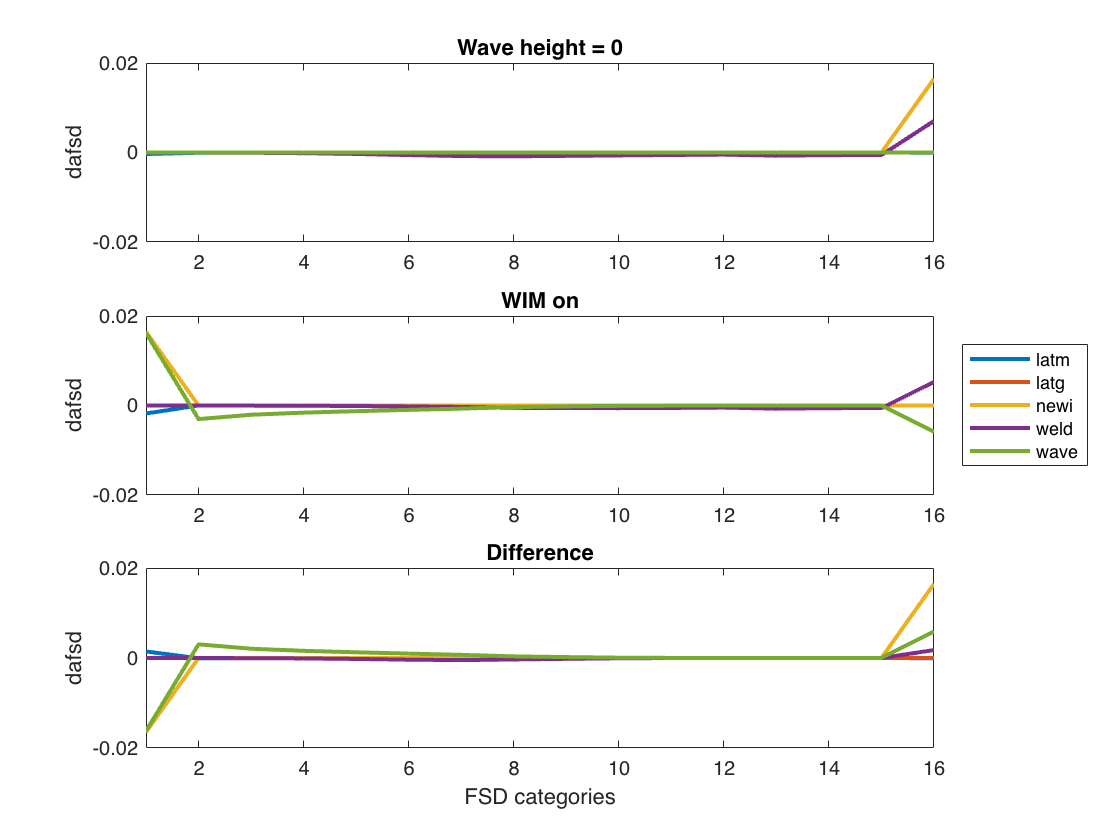

% Plot the change of FSD vs FSD category in that same cell as before
clear t1 t2
bounds = 0.02;
figure(8);
t3 = tiledlayout(3,1,'TileSpacing','compact');
%title(t3,sprintf('Cell at (%g S, %g E)',lat(xcell,ycell),lon(xcell,ycell)))
nexttile
plot(data2','LineWidth',2)
xlim([1,16])
ylabel('dafsd')
ylim([-bounds,bounds])
title(sprintf('Wave height = 0',lat(xcell,ycell),lon(xcell,ycell)))
nexttile
plot(data3','LineWidth',2)
legend({'latm','latg','newi','weld','wave'},'Location','eastoutside')
xlim([1,16])
ylabel('dafsd')
ylim([-bounds,bounds])
title(sprintf('WIM on',lat(xcell,ycell),lon(xcell,ycell)))
nexttile
plot(data2'- data3','LineWidth',2)
xlabel('FSD categories')
xlim([1,16])
ylabel('dafsd')
ylim([-bounds,bounds])
title('Difference')

By looking at the same cell as before, we now see the effect of waves. Notably, the presence of non-zero wave height changes the production of a new large grease ice and forms small pancake ice in the smallest FSD category. Moreover, when waves are significant there is an uptick in welding to the largest floe size category.

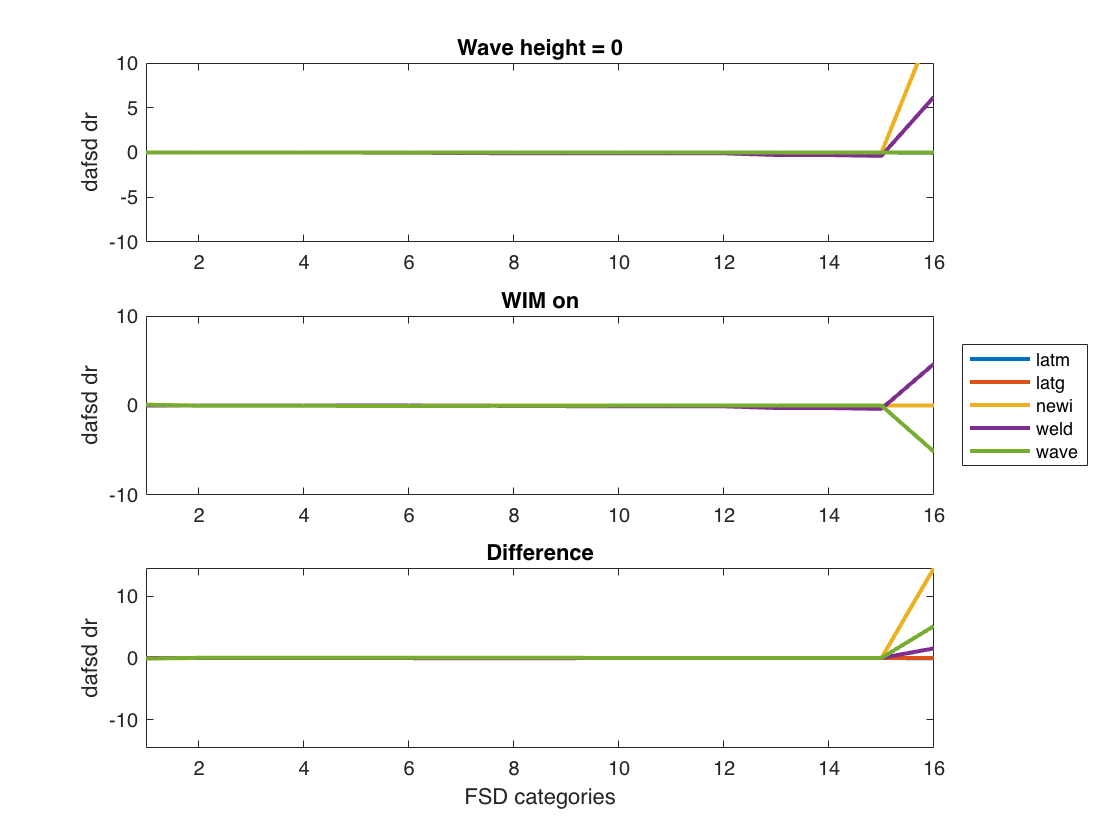

% Plot the change in areal concentration
figure(9) 
close all
clear t1 t2
t4 = tiledlayout(3,1,'TileSpacing','compact');

nexttile
floe_width_mat = [floe_binwidth;floe_binwidth;floe_binwidth;floe_binwidth;floe_binwidth];
plot(data2'.*floe_width_mat','LineWidth',2)
ylabel('dafsd dr')
ylim([-10,10])
xlim([1,16])
title(sprintf('Wave height = 0',lat(xcell,ycell),lon(xcell,ycell)))
nexttile
floe_width_mat = [floe_binwidth;floe_binwidth;floe_binwidth;floe_binwidth;floe_binwidth];
plot(data3'.*floe_width_mat','LineWidth',2)
legend({'latm','latg','newi','weld','wave'},'Location','eastoutside')
ylabel('dafsd dr')
xlim([1,16])
ylim([-10,10])
title('WIM on')
nexttile
plot((data2'- data3').*floe_width_mat','LineWidth',2)
xlabel('FSD categories')
xlim([1,16])
ylabel('dafsd dr')
ylim([-max(max(abs((data2'- data3').*floe_width_mat'))),max(max(abs((data2'- data3').*floe_width_mat')))])
title('Difference')

%title(t4,sprintf('Cell at (%g S, %g E)',lat(xcell,ycell),lon(xcell,ycell)))

When we take the change in ice areal concentration the picture looks very different. We don't see the production of pancake ice, rather it appears as if no ice is forming, but this is not true!

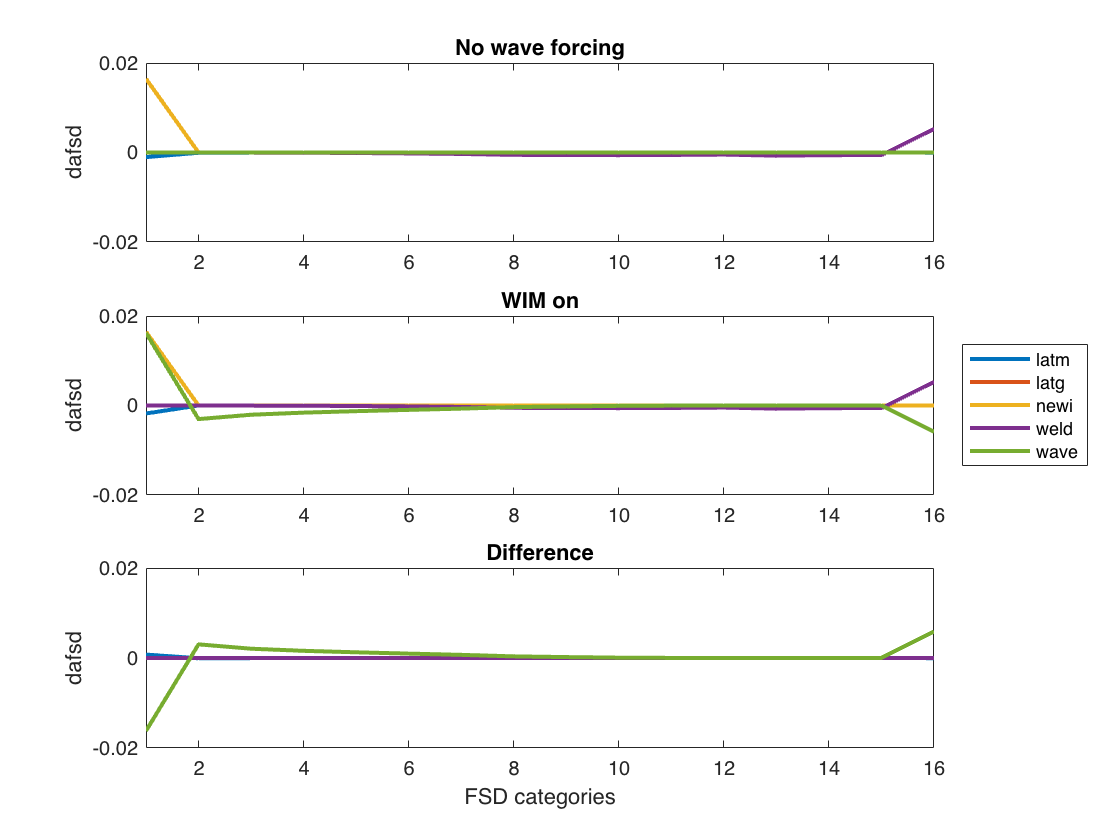

% No forcing vs WIM: Plot the change of FSD vs FSD category in that same cell as before
clear t1 t2
bounds = 0.02;
f9 = figure(10);
t5 = tiledlayout(3,1,'TileSpacing','compact');
%title(t5,sprintf('Cell at (%g S, %g E)',lat(xcell,ycell),lon(xcell,ycell)))
nexttile
plot(data1','LineWidth',2)
xlim([1,16])
ylabel('dafsd')
ylim([-bounds,bounds])
title(sprintf('No wave forcing',lat(xcell,ycell),lon(xcell,ycell)))
nexttile
plot(data3','LineWidth',2)
legend({'latm','latg','newi','weld','wave'},'Location','eastoutside')
xlim([1,16])
ylabel('dafsd')
ylim([-bounds,bounds])
title(sprintf('WIM on',lat(xcell,ycell),lon(xcell,ycell)))
nexttile
plot(data1'- data3','LineWidth',2)
xlabel('FSD categories')
xlim([1,16])
ylabel('dafsd')
ylim([-bounds,bounds])
title('Difference')

When we compare the no wave forcing with WIM, we see little difference in the new floe production. This is as in both cases the smallest FSD was assigned a new floe. The only difference in these results is that now wave induced ice fracturing transports larger floes into the smallest category.

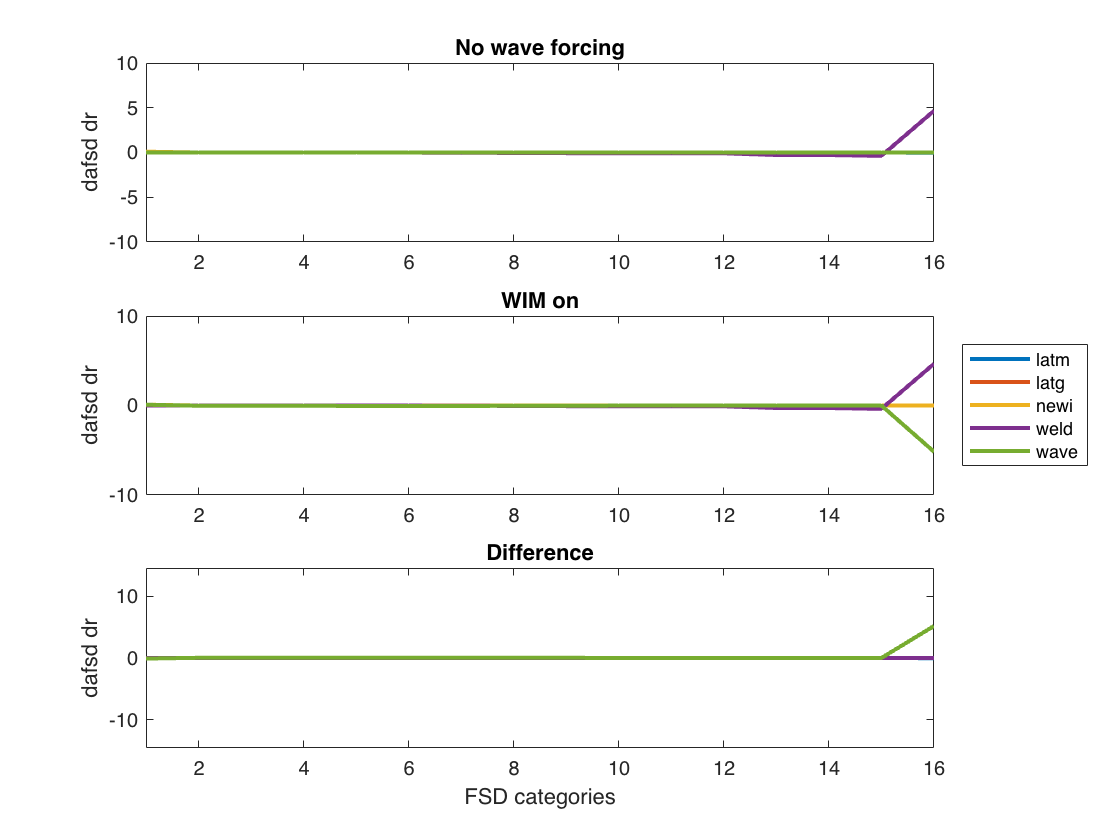

% No forcing vs WIM: Plot the change in areal concentration
f10 = figure(11);
close all
clear t1 t2
t6 = tiledlayout(3,1,'TileSpacing','compact');
%title(t6,sprintf('Cell at (%g S, %g E)',lat(xcell,ycell),lon(xcell,ycell)))
nexttile
floe_width_mat = [floe_binwidth;floe_binwidth;floe_binwidth;floe_binwidth;floe_binwidth];
plot(data1'.*floe_width_mat','LineWidth',2)
ylabel('dafsd dr')
ylim([-10,10])
xlim([1,16])
title(sprintf('No wave forcing',lat(xcell,ycell),lon(xcell,ycell)))
nexttile
floe_width_mat = [floe_binwidth;floe_binwidth;floe_binwidth;floe_binwidth;floe_binwidth];
plot(data3'.*floe_width_mat','LineWidth',2)
legend({'latm','latg','newi','weld','wave'},'Location','eastoutside')
ylabel('dafsd dr')
xlim([1,16])
ylim([-10,10])
title('WIM on')
nexttile
plot((data1'- data3').*floe_width_mat','LineWidth',2)
xlabel('FSD categories')
xlim([1,16])
ylabel('dafsd dr')
ylim([-max(max(abs((data2'- data3').*floe_width_mat'))),max(max(abs((data2'- data3').*floe_width_mat')))])
title('Difference')

When looking at the areal concentration we only notice the largest floes changing (as they dominate the surface area).